## 9804 Image Processing and Application Lab01

### Geometric Transformation

- Read the image and convert the image intro a grayscale image

- Define the transformation matrix with a rotation angle

- Calculate the boundary of the transformed image and generate an empty calculated size

- Transform each pixel with the transformation matrix and assign the intensity location

- View the transformed image

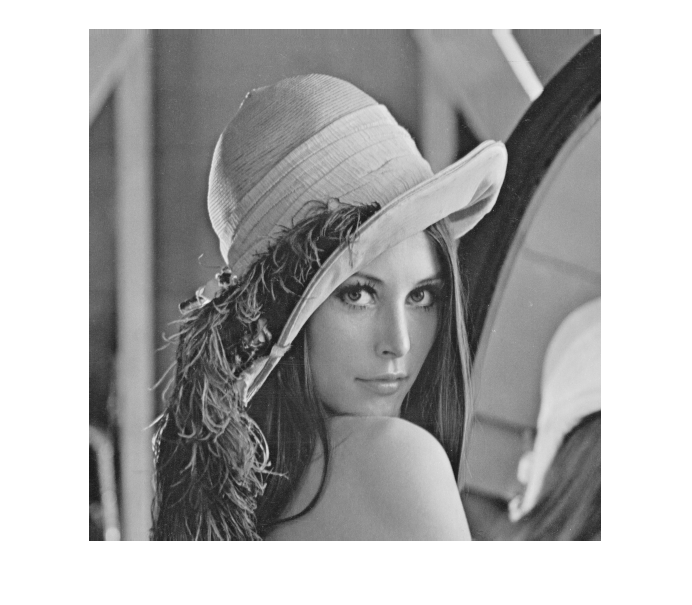

imc = imread('im1.png');% Read the image
img = rgb2gray(imc); % Convert to grayscale. if the supplied image is a grayscale, 
                        %so you don't need to use this step.
imshow(img); % View image


theta = 0.25 * pi;
R = [cos(theta)  sin(theta) 0; ...
     -sin(theta) cos(theta) 0; ...
     0           0          0];

[y_max, x_max] = size(img); % obtaining the size of the image
corners = [0,     0,    1;...
           x_max, 0,    1;...
           0,     y_max,1;...
           x_max, y_max, 1] %corner points of the image

corners =      0     0     1
   512     0     1
     0   512     1
   512   512     1


new_corners = corners*R     %new location of corners

new_corners =          0         0         0
  362.0387  362.0387         0
 -362.0387  362.0387         0
    0.0000  724.0773         0


new_width = round(max(new_corners(:,1)) - min(new_corners(:,1)))

new_width = 724

new_height = round(max(new_corners(:,2)) - min(new_corners(:,2)))

new_height = 724

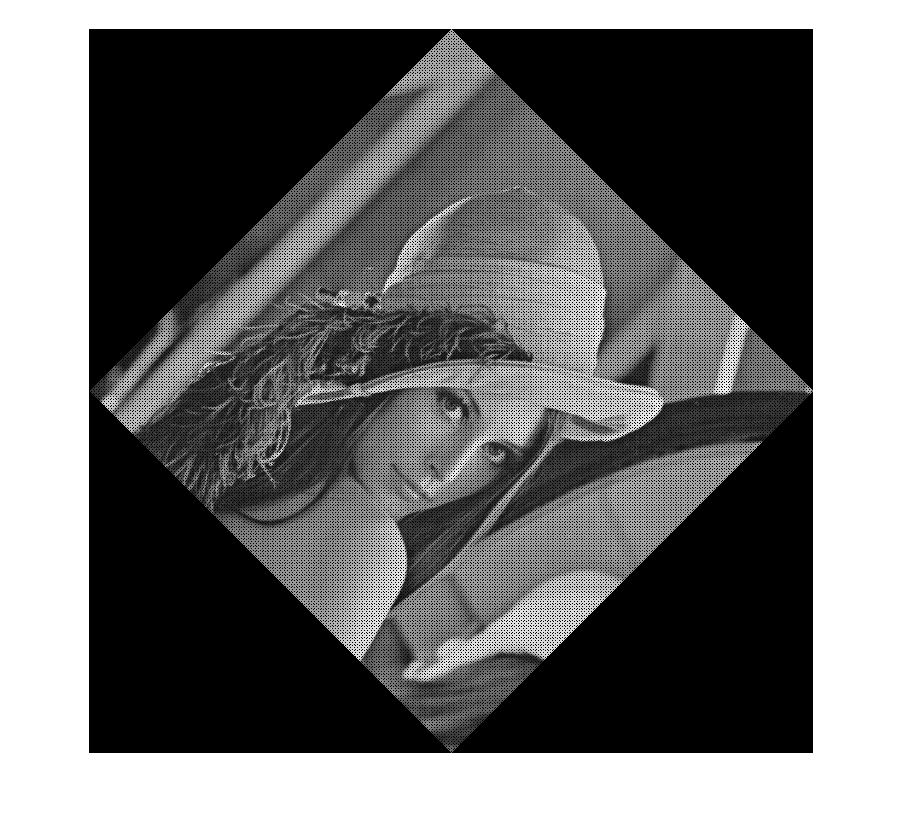

new_img = zeros(new_height, new_width);

min_width = abs(min(new_corners(:,1)));
min_height = abs(min(new_corners(:,2)));

min_width = round(min_width) + 1;
min_height = round(min_height) + 1;

for i = 1 : y_max
    for j= 1 : x_max
        temp = [j-1, i-1, 1] * R;
        x_new = round(temp(1,1)) + min_width;
        y_new = round(temp(1,2)) + min_height;
        new_img(y_new, x_new) = img(i, j);
    end
end

figure;
imshow(new_img, [])